# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
% c0(1) = 0.001;  
% c0(2) = 0.023;
% c1 = 0.0010;  
% c2 = 0.0196;
c1 = 0.001200000000000;
c2 = 0.013720000000000;
tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 0;

a=-2;
b=2;
c=1;

**Target Shape **`h_target`

a=round(a/dx+N/2);
b=round(b/dx+N/2);
h_region = [a;b;c];
H_region = 0.1*ones(size(X));
H_region(1:a)=c;
H_region(b:end)=c;

## **2) **

**Solutions**

[tSpan,D1,D2,X,H0,myObjective_Possition,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c1,c2,h_region);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           147.12         
     1            3          146.183         initial simplex
     2            5          142.879         expand
     3            7          138.245         expand
     4            9          117.837         expand
     5           11          113.875         reflect
     6           15          113.875         shrink
     7           17          113.296         contract outside
     8           19          113.296         contract inside
     9           21            113.2         reflect
    10           23            113.2         contract inside
    11           25            113.2         contract inside
    12           27          113.096         reflect
    13           29          113.096         contract inside
    14           31          113.096         contract inside
    15           33           113.08         reflect
    16           35           113.08         cont

**Figures**


var = [A;N;k;y0]; 
% Set time span
tSpan = [1e-6 tfinal]; 
% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2); % D2
    
h1 = hFinal(history(2,:),X,var,D1,D2,tSpan);
H1 = deval(h1,tfinal);   

h2 = hFinal(history(3,:),X,var,D1,D2,tSpan);
H2 = deval(h2,tfinal); 

h3 = hFinal(history(4,:),X,var,D1,D2,tSpan);
H3 = deval(h3,tfinal);   

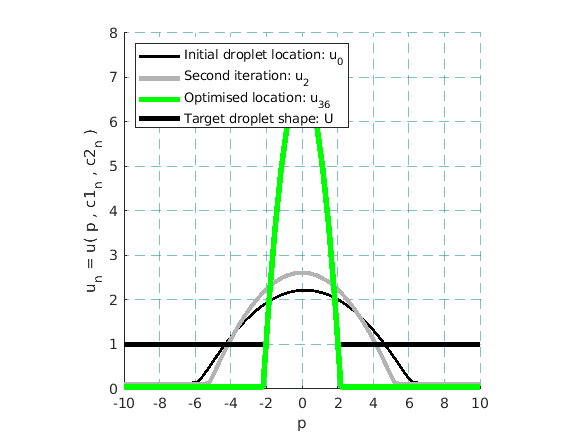


figure;
hold on
pbaspect([2 2 1]);
plot(X,H0,'k-','linewidth',2);
plot(X,H2,'-','Color',[0.7 0.7 0.7],'linewidth',3);
plot(X,H_Sol,'g-','linewidth',4);
plot(X(1:a),H_region(1:a),'k-','linewidth',4);
plot(X(b+1:end),H_region(b+1:end),'k-','linewidth',4);
legend('Initial droplet location: u_0','Second iteration: u_{2}','Optimised location: u_{36}','Target droplet shape: U','Location','northwest');
set(gca,'xtick',-100:2:100);
% title('2-D profile of droplet')
xlabel('p')
ylabel('u_n = u( p , c1_n , c2_n )')
xlim([-10 10]);
ylim([0 8]);
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
hold off

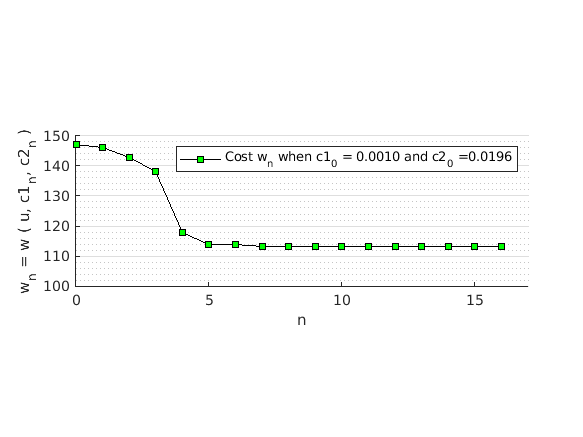

n = size(history);
n = n(1);
C1 = history(:,1);
C2 = history(:,2);
lineHi = 0:1:n-1;

figure;
plot(lineHi,History,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g');
pbaspect([2 1 1]);
box off
% title('Iterative evolution of droplet distance to optimal location');
ylabel('w_n = w ( u, c1_n, c2_n )');
xlabel('n');
legend('Cost w_n when c1_0 = 0.0010 and c2_0 =0.0196');
set(gca,'xtick',0:5:100);
set(gca,'ytick',0:10:500);
xlim([0 17]);
ylim([100 150]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([3 1 1]);

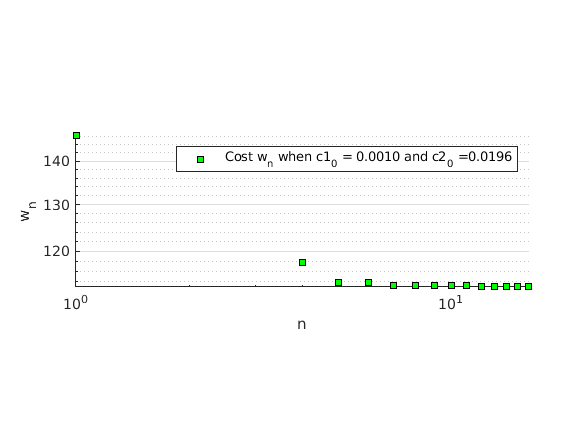


figure;
loglog(lineHi,History,'ks',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
box off
% title('Iterative evolution of droplet distance to optimal location');
legend('Cost w_n when c1_0 = 0.0010 and c2_0 =0.0196');
ylabel('w_n');
xlabel('n');
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([3 1 1]);

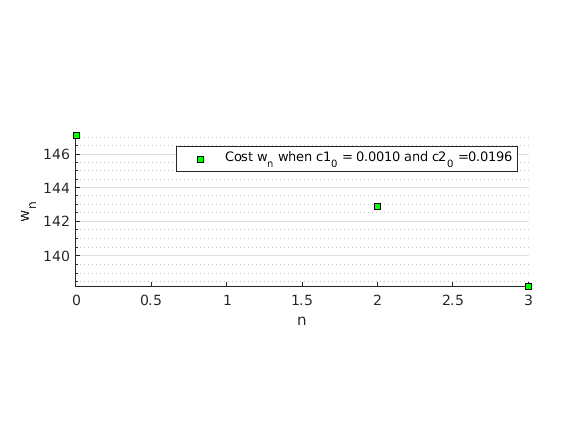



% figure;
% semilogy(lineHi(1:4),History(1:4),'ks',...
%     'MarkerSize',6,...
%     'MarkerFaceColor','g',...
%     'LineWidth',1);
% box off
% % title('Iterative evolution of droplet distance to optimal location');
% legend('Cost w_n when c1_0 = 0.0010 and c2_0 =0.0196');
% ylabel('w_n');
% xlabel('n');
% ax = gca;
% ax.GridLineStyle = '-';
% ax.XGrid = 'off';
% ax.YGrid = 'on';
% ax.MinorGridLineStyle =':';
% ax.XMinorGrid = 'off';
% ax.YMinorGrid = 'on';
% pbaspect([3 1 1]);

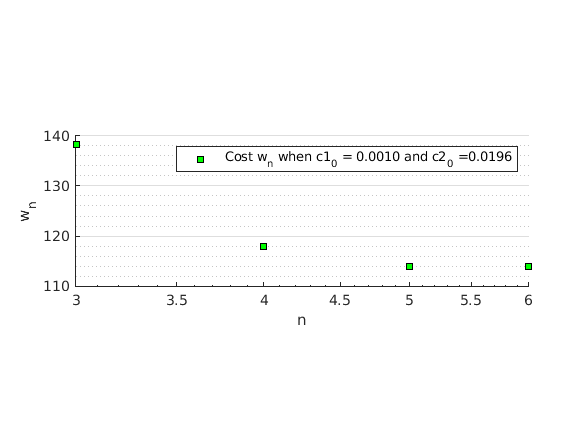

% 
% figure;
% semilogx(lineHi(4:7),History(4:7),'ks',...
%     'MarkerSize',6,...
%     'MarkerFaceColor','g',...
%     'LineWidth',1);
% box off
% % title('Iterative evolution of droplet distance to optimal location');
% legend('Cost w_n when c1_0 = 0.0010 and c2_0 =0.0196');
% ylabel('w_n');
% xlabel('n');
% ax = gca;
% ax.GridLineStyle = '-';
% ax.XGrid = 'off';
% ax.YGrid = 'on';
% ax.MinorGridLineStyle =':';
% ax.XMinorGrid = 'off';
% ax.YMinorGrid = 'on';
% pbaspect([3 1 1]);

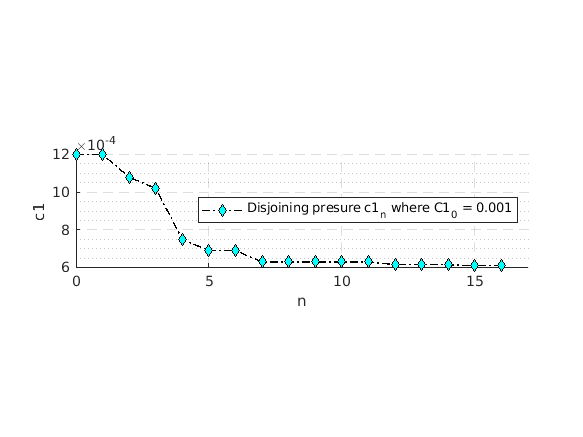



figure;
plot(lineHi,C1,'k-.diamond',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([2 1 1]);
box off
ylabel('c1');
xlabel('n');
legend('Disjoining presure c1_n where C1_0 = 0.001','Location','east');
set(gca,'xtick',0:5:100);
xlim([0 17]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([4 1 1]);

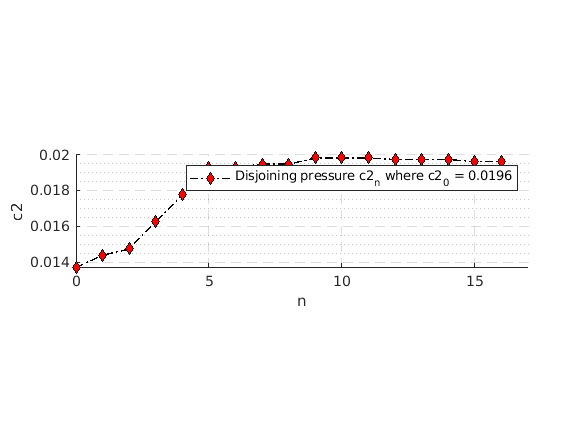


figure;
S2 = plot(lineHi,C2,'k-.diamond',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
pbaspect([2 1 1]);
box off
ylabel('c2');
xlabel('n');
legend('Disjoining pressure c2_n where c2_0 = 0.0196');
set(gca,'xtick',0:5:100);
xlim([0 17]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([4 1 1]);

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis